# 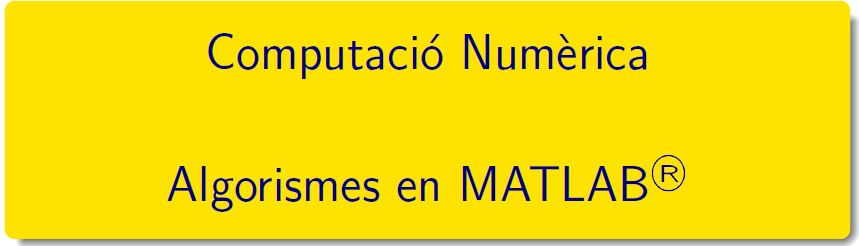

# Pràctica 1 - Conceptes Bàsics

## 1. Introducció a MATLAB

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

## 2. Exemple mètode iteratiu: convergència 

El mètode iteratiu següent: convergeix a $\sqrt{2}$


$$x_k=\displaystyle\frac{1}{2}\left (x_{k-1}+\displaystyle\frac{2}{x_{k-1}}\right )\quad k\ge 1\ i\ x_0=3\,.$$


Calcular el valor $$x_{10}$$ fent ús de les instruccions

- bucle for

- bucle while

En tots els casos comparar el resultat obtingut amb el valor $$\sqrt{2} $$ . 

Calculeu els decimals correctes i les cifres significatives en cada iteració. Presenteu els resultats obtinguts en una taula.

**Solucions**

Calculem 5  iterats, no conservem els valors càlculats

clearvars
x=3;
k = 0;
while(k <5)
    x= (x+2/x)*0.5
    k=k+1;
end

x = 1.8333

x = 1.4621

x = 1.4150

x = 1.4142

x = 1.4142

errores(sqrt(2),x)

ans = 1.6653e-14

Calculem 5 iterats, conservem els valors càlculats

clearvars
k = 1;
x(k)=3;
while(k <5)
    k=k+1;
    x(k)= (x(k-1)+2/x(k-1))*0.5;
end
[ea,~, ~,xs]= errores(sqrt(2),x);

Calculeu els 5 primers iterats, totes les iteracions en un vector, resultat en una estructura table.

format longG
TR = [0:k-1; x; ea; xs]';
T = array2table(TR,"VariableNames",{'k','x','error absolut','xifres significatives'});
disp(T)

    k           x               error absolut        xifres significatives
    _    ________________    ____________________    _____________________

    0                   3         1.5857864376269              0          
    1    1.83333333333333       0.419119770960238              0          
    2    1.46212121212121       0.047907649748117              1          
    3     1.4149984298948    0.000784867521707922              2          
    4     1.4142137800472    2.17674102520604e-07              6          



### Qüestió oberta

Calculeu els ¿¿¿tots ???  els iterats, com s'atura el bucle

format shortG
k = 1;
x(k)=3;
control = 1

control =      1


while(k<100 && control > eps)
    k=k+1;
    x(k)= (x(k-1)+2/x(k-1))*0.5;
    control =abs(x(k)-sqrt(2))
end

control =       0.41912


control =      0.047908


control =    0.00078487


control =    2.1767e-07


control =    1.6653e-14


control =    2.2204e-16


## 3. Aritmètica de PUNT FLOTANT

The memory format of an IEEE 754 double-precision floating-point value.

$fl(x)=(-1)^s\cdot \left(1+\frac{F}{2^{52}}\right)\cdot 2^{E-1023}$ per $s$ un bit, per $E$, l'exponent $11$ bits i per $F$, la part fraccionaria $52$bits

 Illustrated in byte-form, the exponent and fraction bits are distributed as:

[image: IEEE_754_Double_Floating_Point_Format.svg]   [crèdits imatge](https://commons.wikimedia.org/wiki/File:IEEE_754_Double_Floating_Point_Format.svg)

*0*0000000 0000**0000 00000000 00000000 00000000 00000000 00000000 00000000**

[Floating Point Arithmetic Before IEEE 754](https://blogs.mathworks.com/cleve/2019/01/18/floating-point-arithmetic-before-ieee-754/)

[A Glimpse into Floating-Point Accuracy](https://blogs.mathworks.com/loren/2006/08/23/a-glimpse-into-floating-point-accuracy/?s_tid=srchtitle)  o  [Floating Point Numbers](https://es.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html)

**Exercici 1.- Nombres binaris i nombres decimals**

- Convertim el nombre 17.25 a binari:

x = 17.25

x =         17.25


- part entera, restes de dividir per 2

y = fix(x); r = rem(y,2); T = [y,r];
y = fix(y/2); r = rem(y,2), T = [T; y,r];

r =      0



% b = num2str(T(end:-1:1,2));
% fprintf('El nombre %f en binari és %s\n',fix(x),b)

- part fraccionaria, multipliquem per 2 i ens quedem amb la part entera

z = x-fix(x);
y = 2*z; r = fix(y);  T = [z,r]; z = y-r;
y = 2*z; r = fix(y);  T = [T; z,r], z = y-r;

T =          0.25            0
          0.5            1



% b2 = num2str(T(:,2));
% fprintf('El nombre %f en binari és %s\n',x-fix(x),b2)
% fprintf('El nombre %f en binari és %s.%s\n',x,b,b2)

**Exercici 2.- Aritmètica de punt flotant de 64 bits**

### LECTURA OBLIGATÒRIA: [Floating Points: IEEE Standard Unifies Arithmetic Model](https://es.mathworks.com/company/newsletters/articles/floating-points-ieee-standard-unifies-arithmetic-model.html?s_tid=answers_rc2-3_p6_Topic)

Toby Driscoll (2021). IEEE 754 binary representation ([https://www.mathworks.com/matlabcentral/fileexchange/25326-ieee-754-binary-representation),](https://www.mathworks.com/matlabcentral/fileexchange/25326-ieee-754-binary-representation),) MATLAB Central File Exchange. Retrieved February 17, 2022.

[S,E,F] = ieee754(17)

S = '0'

E = '10000000011'

F = '0001000000000000000000000000000000000000000000000000'

**EXEMPLES**

**Avoiding Common Problems with Floating-Point Arithmetic**

Example 1 — Round-Off or What You Get Is Not What You Expect

- 4/3 no té fracció binària exacte

format short
a = 4/3

a = 1.3333

b = a-1

b = 0.3333

c = b+b+b

c = 1.0000

c == 1, abs(c-1)>= eps

ans = logical
   0


ans = logical
   1


[S,E,F] = ieee754(1)

S = '0'

E = '01111111111'

F = '0000000000000000000000000000000000000000000000000000'

- 0.1 no té representació binària exacte

[S,E,F] = ieee754(c)

S = '0'

E = '01111111110'

F = '1111111111111111111111111111111111111111111111111110'

- L'ordre de les operacions pot fer variar el resultat del càlcul

- Hi ha "gaps" entre els números de punt flotant.  

- La representació de $\pi$ comporta que 

sin(pi)==0

ans = logical
   0


**Example 2 — Catastrophic Cancellation**

**Example 3 — Floating-Point Operations and Linear Algebra**

L'arrodoniment, la cancel·lació i altres caracterítiques de l'aritmètica de coma flotant es combinen per produir càlculs sorprenents en resoldre els problemes de l'àlgebra lineal. MATLAB adverteix que la següent matriu A està mal condicionada i, per tant, el sistema Ax = b pot ser sensible a petites pertorbacions:

A = [10 1; 3 0.3]

A =    10.0000    1.0000
    3.0000    0.3000


b = [11 3.3]'

b =    11.0000
    3.3000


x = linsolve(A,b), det(A)

x =    Inf
  -Inf


ans = 0

**Example 4 — "Soroll numèric"**

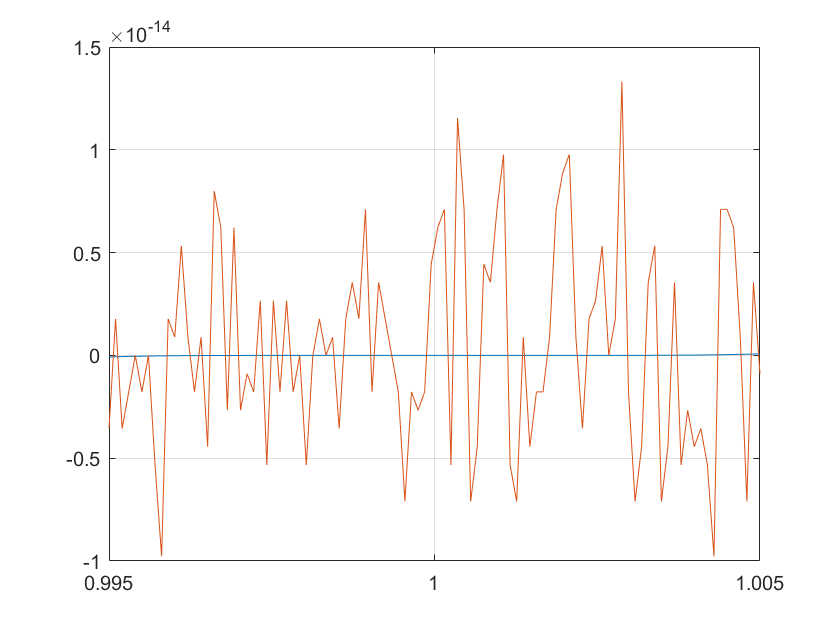

x = linspace(0.995,1.005);
y =x.^7 - 7*x.^ 6 + 21*x.^5 - 35*x.^4 + 35*x.^3 -21*x.^2 + 7*x - 1;
plot(x,(x-1).^7),grid
hold on
plot(x,y)
hold off

## 4. Algorismes: Estabilitat numèrica i problemes ben condicionats

### Practiquem les funcions

#### Exercici 6. [Funcions anònimes](https://es.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

`h = @(``arglist``)``anonymous_function`

**6**  Avalueu les funcions  $\displaystyle f(x)=\sqrt{x^2+1}-1\,,\quad\quad
g(x)=x^2/{\left( \sqrt{x^2+1}+1\right) }$ per a la successió de valors de $x_n= 8^{-n}\,,\ n\geq 1\,.$ 

Encara que $f(x)=g(x)$, l'ordinador dóna resultats diferents. Feu un joc de proves prenent $2^{-n},5^{-n},7^{-n},10^{-n}, \dots$

Quins resultats són de fiar i quins no? Per què?  Expliqueu la vostra resposta

#### Exercici 8. [Funcions en Live script](https://es.mathworks.com/help/matlab/ref/function.html)

`function f = nom_fun(``arglist``)`

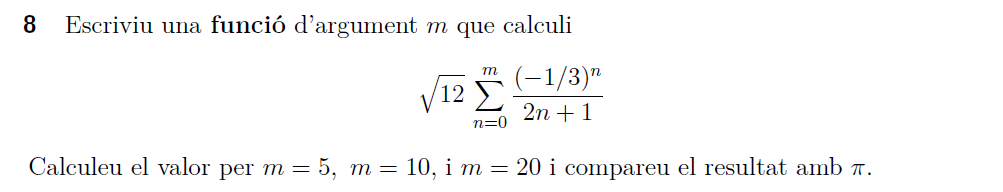

**11** **Càlcul d'integrals per recurrència**	

	Per calcular les integrals$\displaystyle I_{n}=\int_{0}^{1} x^n e^{x-1}dx\,,\quad n\ge~1\,,$ 	dispossem de dos mètodes iteratius diferents:

	            
$$$$\begin{array}{llrr}
	\text{ a)}\quad I_{n-1}&=\displaystyle\frac{1-I_n}{n}, & n\ge 2 &{\rm\ on\ }I_{50}=0\,,\\  & & & \\
	\text{ b)}\quad I_n&=1-nI_{n-1}, & n\ge 2 &{\rm\ on\ }I_1=1/e\,.
	\end{array}$$$$


	Calculeu $$I_{30}$\,$ pels dos mètodes. Obteniu els mateixos resultats ? Sabrieu donar una explicació?

- apartat a)

- apartat b)

- valor aproximat per integració numèrica

- Taula comparativa de resultats

- Taula comparativa d'errors

## Pràctica

## 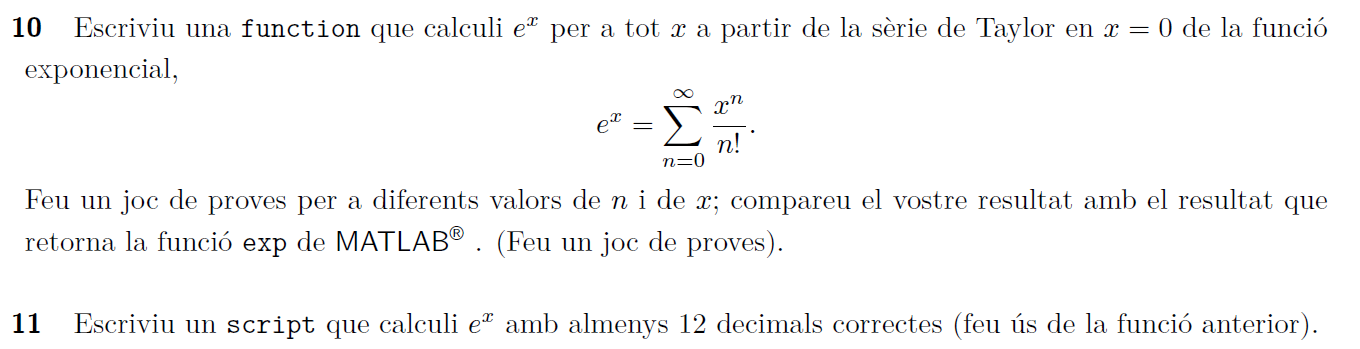     

`Document preparat per M. Àngela Grau Gotés, 15 de febrer de 2023`